% 定义角度 theta，从 0 到 pi
theta = linspace(0, pi, 100);  % 100 个点

% 计算单位圆上半圆上的点
z = exp(1i * theta);

% 定义映射函数
mapping_function = @(z) (z + 1./z) / 2;

% 对单位圆上半圆上的点应用映射
z_mapped = mapping_function(z);

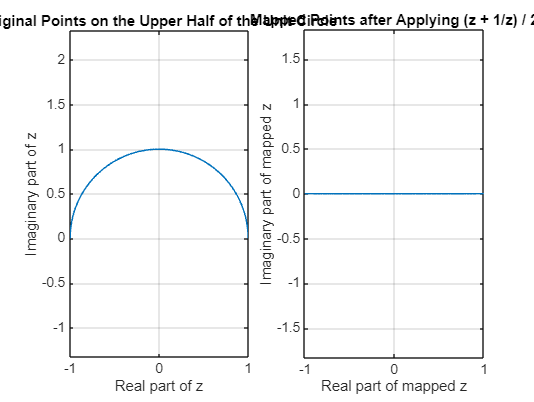

% 绘制原始单位圆上半圆上的点
figure;
subplot(1, 2, 1);
plot(real(z), imag(z), 'LineWidth', 1);
xlabel('Real part of z');
ylabel('Imaginary part of z');
title('Original Points on the Upper Half of the Unit Circle');
axis equal;
grid on;

% 绘制映射后的点
subplot(1, 2, 2);
plot(real(z_mapped), imag(z_mapped), 'LineWidth', 1);
xlabel('Real part of mapped z');
ylabel('Imaginary part of mapped z');
title('Mapped Points after Applying (z + 1/z) / 2');
axis equal;
grid on;

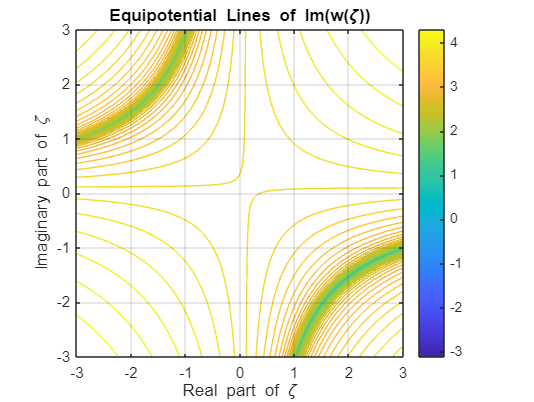

b=i*(-3);
% 定义第一个函数 w(z) = i * log(z)


w = @(zeta) 1i * log(zeta);

%w = @(zeta) i*log(zeta-b)-i*log(1./zeta-conj(b));

% 定义第二个函数 z = 3 * zeta
zeta = @(z)  z-sqrt(z^2-1);% error because .^   . lost

% 组合函数 w(zeta) = w(z(zeta))
w_z = @(z) w(zeta(z));

% 定义网格的范围和分辨率
x = linspace(-3, 3, 500);
y = linspace(-3, 3, 500);
[X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;

% 计算 w(zeta) 的值
W_grid = w_z(z_grid);

% 提取实部和虚部
W_real = real(W_grid);
W_imag = imag(W_grid);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 70);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

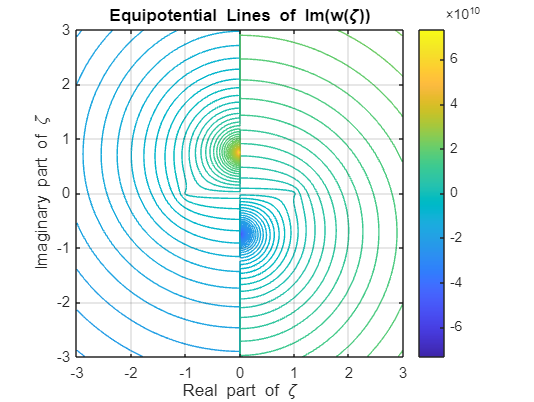

% wt =@(z) 1i * log(z+i*3) -1i * log(1./z-i*3);

% Define constants
q = 1;
epsilon_0 = 8.854187817e-12; % Vacuum permittivity
epsilon_r = 2; % Relative permittivity
d = 1; % Distance parameter

qt=(q / (2 * pi * epsilon_0 * epsilon_r));
qi=(q * (epsilon_r-1)/ ( pi * epsilon_0 * epsilon_r * (epsilon_r + 1)));

%min=@(zeta) zeta.*(1-1e-5);
f_up=@(zeta) zeta-sqrt(zeta.^2-1) ;
f_down=@(zeta) zeta+sqrt(zeta.^2-1) ;


wt=@(z) i*(qt+qi)*(log(z+sqrt(z.^2-1)+i*2)-log(1./(z+sqrt(z.^2-1))-i*2));
%wt=@(zeta) i*log(zeta+i*2)-i*log(1./(zeta)-i*2);
% 定义网格的范围和分辨率
x = linspace(-3, 3, 500);
y = linspace(-3, 3, 500);
[X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;

% 计算 w(zeta) 的值
W_grid_up = wt(z_grid);
W_grid_down = wt(z_grid);

%
W_grid = zeros(size(X));
% Apply V_lower for y < 0 and V_upper for y > 0
% W_grid( X < 0) = W_grid_up(X( X < 0), Y( X < 0));
% W_grid( X > 0) = W_grid_down(X( X > 0), Y( X > 0));

% Apply V_lower for y < 0 and V_upper for y > 0
W_grid(Y > 0) = W_grid_down(Y > 0); % 使用逻辑条件来选择相应的区域
W_grid(Y < 0) = W_grid_up(Y < 0);


% 提取实部和虚部
W_real = real(W_grid);
W_imag = imag(W_grid);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 80);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

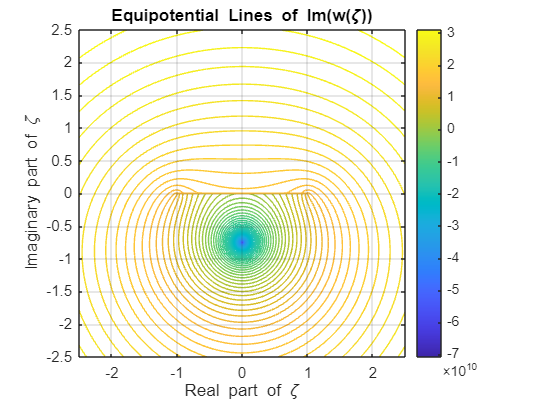

%upper volt
%lower voltage

% Define constants
q = 1;
epsilon_0 = 8.854187817e-12; % Vacuum permittivity
epsilon_r = 2; % Relative permittivity
d = 1; % Distance parameter

qt=(q / (2 * pi * epsilon_0 * epsilon_r));
qi=(q * (epsilon_r-1)/ ( pi * epsilon_0 * epsilon_r * (epsilon_r + 1)));

% wt =@(z) 1i * log(z+i*3) -1i * log(1./z-i*3);

min=@(zeta) zeta.*(1-1e-5);
f_up=@(zeta) (zeta+sqrt(zeta.^2-1)) ;
f_down=@(zeta) (zeta-sqrt(zeta.^2-1)) ;


%wt=@(z) i*log(z+sqrt(z.^2-1)+i*2)-i*log(1./(z+sqrt(z.^2-1))-i*2);
wt=@(zeta) i*(qt+qi)*log(zeta+i*2)-i*log(1./(zeta)-i*2);
% 定义网格的范围和分辨率
x = linspace(-2.5, 2.5, 600);
y = linspace(-2.5, 2.5, 600);
[X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;

% 计算 w(zeta) 的值
W_grid_up = wt(f_up(z_grid));
W_grid_down = wt(f_down(z_grid));

%
W_grid = zeros(size(X));

% Apply V_lower for y < 0 and V_upper for y > 0

W_grid(X < 0.) = W_grid_down(X < 0.); % 使用逻辑条件来选择相应的区域
W_grid(X > 0) = W_grid_up(X > 0);


% 提取实部和虚部
W_real = real(W_grid);
W_imag = imag(W_grid);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 80);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;


%lower voltage

% Define constants
q = 1;
epsilon_0 = 8.854187817e-12; % Vacuum permittivity
epsilon_r = 2; % Relative permittivity
d = 1; % Distance parameter
% 
% % Define the range for x and y
 x = linspace(-2.5, 2.5, 600);
 y = linspace(-2.5, 2.5, 600);
 [X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;
% Define the potential functions

qt=(q / (2 * pi * epsilon_0 * epsilon_r))

qt = 8.9876e+09

qi=(q * (epsilon_r-1)/ ( pi * epsilon_0 * epsilon_r * (epsilon_r + 1)))

qi = 5.9917e+09

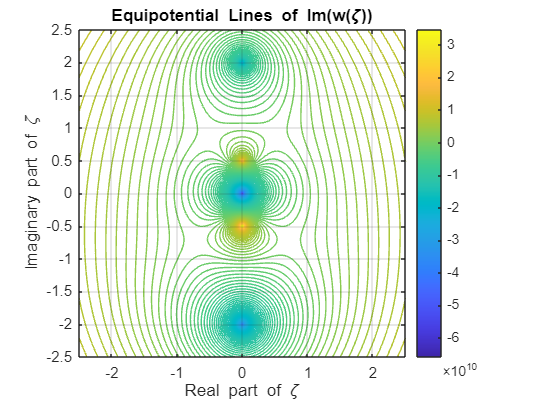

wt=@(zeta) i*(qt)*( log(zeta+i*2)-log(1./(zeta)-i*2) );
wi=@(zeta) i*qi*( log(zeta-i*2)-log(1./(zeta)+i*2));

w_low=@(zeta)wt(zeta)+wi(zeta);

W_lower_grid = w_low(z_grid);

% 提取实部和虚部
W_real = real(W_lower_grid);
W_imag = imag(W_lower_grid);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 150);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

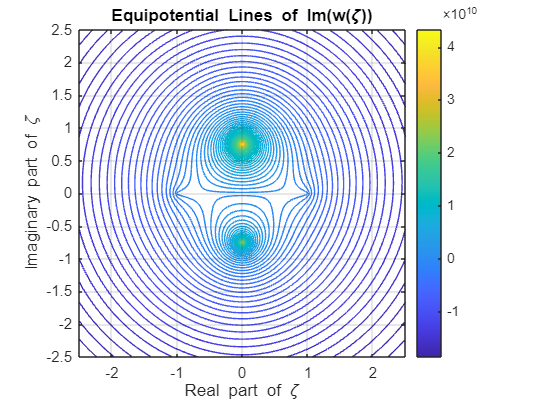


% % Define the range for x and y
 x = linspace(-2.5, 2.5, 600);
 y = linspace(-2.5, 2.5, 600);
 [X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;
% Define the potential functions

% 计算 w(zeta) 的值
W_map_lower_up_grid = w_low(f_up(z_grid));
W_map_lower_down_grid = w_low(f_down(z_grid));

%
W_map_lower = zeros(size(X));

% Apply V_lower for y < 0 and V_upper for y > 0

W_map_lower(X < 0) = W_map_lower_up_grid(X < 0); % 使用逻辑条件来选择相应的区域
W_map_lower(X > 0) = W_map_lower_down_grid(X > 0);

% 提取实部和虚部
W_real = real(W_map_lower);
W_imag = imag(W_map_lower);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 80);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

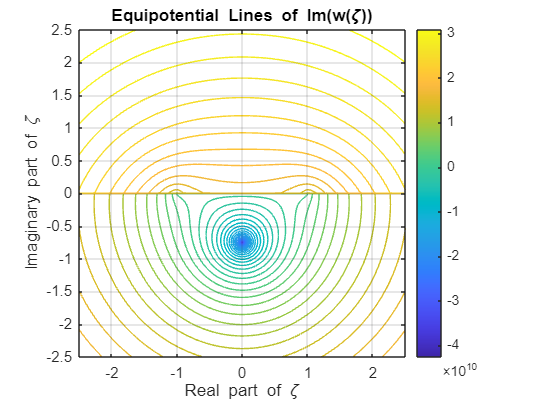

% % Define the range for x and y
 x = linspace(-2.5, 2.5, 600);
 y = linspace(-2.5, 2.5, 600);
 [X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;
% Define the potential functions

% 计算 w(zeta) 的值

%
whole_map = zeros(size(X));


whole_map(Y <= 0.) = W_map_lower(Y <= 0.);%W_map_lower(X < 0); % 使用逻辑条件来选择相应的区域
whole_map(Y >= 0.) = W_grid(Y >= 0.);

% 提取实部和虚部
W_real = real(whole_map);
W_imag = imag(whole_map);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 50);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;